**Occupancy Grid Mapping**

clear;
close all;

% Load data
orebroData = load('OrebroData-1.mat');
frCampus = load('fr-campus.csv');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Initialize common parameters
% Number of cells to consider as occupied from the hit cells of the seansor readings
occupancyCellSize = 1; 
% Whether to plot live
livePlotting = false;
% Resolution of each grid
gridResolution = 1;

% Initialize log-format of occupancy probability and prior
log_occupied = log(0.75 / (1 - 0.75));
log_free = log(0.25 / (1 - 0.25));
log_prior = log(0.5 / (1 - 0.5));
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Orebro mapping
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Extract the sensor readings and poses of the robot
orebroSensorReadings = orebroData.FLASER(:, 3:183); % 181 sensor readings
orebroRobotPoses = orebroData.FLASER(:, 184:186); % x, y, theta

% Initialize specific parameters for Orebro
orebroInflationFactor = 1;
orebroGridResolution = 0.1;
orebroGridSize = [75, 75] ./ orebroGridResolution;
orebroMaxRange = max(orebroSensorReadings(:)) * 0.2;
orebroMap = ones(orebroGridSize) .* 0.5;
orebroLogMap = log(orebroMap ./ (1 - orebroMap));

% Mapping algorithm
disp('Mapping Orebro')

Mapping Orebro


tic
[orebroLogMap, orebroPath] = OccupancyMapping(orebroLogMap, orebroSensorReadings, orebroRobotPoses, log_occupied, log_free, log_prior, orebroGridResolution, orebroMaxRange, occupancyCellSize, livePlotting);
toc

Elapsed time is 2.800299 seconds.



% Convert back to probabiliy map
orebroMap = 1 - (1 ./ (1 + exp(orebroLogMap)));
orebroMap = InflateMap(orebroMap, orebroInflationFactor);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% fr campus mapping
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Extract the sensor readings and poses of the robot
frCampusSensorReadings = frCampus(:, 2:361); % 360 sensor readings
frCampusRobotPoses = frCampus(:, 362:364); % x, y, theta

% Initialize specific parameters for fr campus
frCampusInflationFactor = 0;
frCampusGridSize = [300, 300] ./ gridResolution;
frCampusMaxRange = max(frCampusSensorReadings(:)) * 0.25;
frCampusMap = ones(frCampusGridSize) .* 0.5;
frCampusLogMap = log(frCampusMap ./ (1 - frCampusMap));
disp('Mapping fr campus')

Mapping fr campus


tic
[frCampusLogMap, frCampusPath] = OccupancyMapping(frCampusLogMap, frCampusSensorReadings, frCampusRobotPoses, log_occupied, log_free, log_prior, gridResolution, frCampusMaxRange, 4, livePlotting);
toc

Elapsed time is 11.703250 seconds.


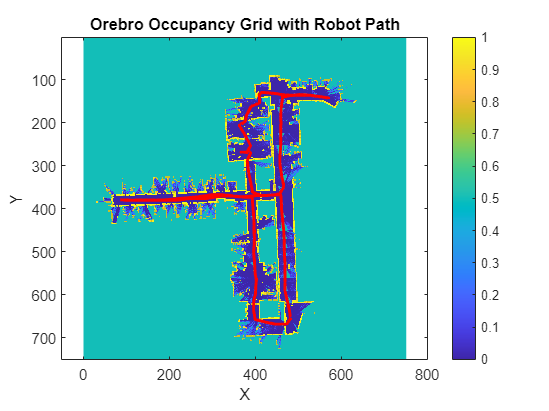


% Convert back to probabiliy map
frCampusMap = 1 - (1 ./ (1 + exp(frCampusLogMap)));
frCampusMap = InflateMap(frCampusMap, frCampusInflationFactor);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Plot maps
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Plot the occupancy map of Orebro
figure;
imagesc(orebroMap');
colorbar;
title('Orebro Occupancy Grid with Robot Path');
xlabel('X');
ylabel('Y');
hold on;

plot(orebroPath(:, 1), orebroPath(:, 2), 'r', 'LineWidth', 2);

hold off;
axis equal;

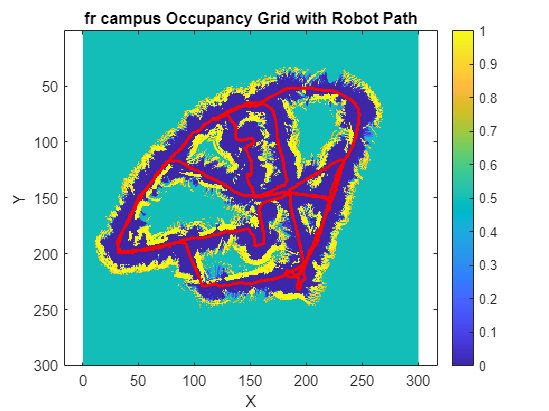


% Plot the occupancy map of fr campus
figure;
imagesc(frCampusMap');
colorbar;
title('fr campus Occupancy Grid with Robot Path');
xlabel('X');
ylabel('Y');
hold on;

% Plot path in grid coordinates
plot(frCampusPath(:, 1), frCampusPath(:, 2), 'r', 'LineWidth', 2);
hold off;
axis equal;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

**A* Orebro**

[rowIndices, colIndices] = find(orebroMap < 0.1);
indices = [rowIndices, colIndices];


%startIndices = indices(randi(size(indices, 1)), :);
%goalIndices = indices(randi(size(indices, 1)), :);
startIndices = [91, 379];
goalIndices = [558, 133];

obstacleMap = orebroMap;
for i = 1:size(obstacleMap, 1)
    for j = 1:size(obstacleMap, 2)
        if obstacleMap(i, j) > 0.4
            obstacleMap(i, j) = Inf;
        end
    end
end

% run Dijkstra's algorithm
disp("Orebro A*")

Orebro A*


tic
pathAStar = AStar(obstacleMap, startIndices, goalIndices);

PushCounter: 53279
PopCounter: 33430


toc

Elapsed time is 45.218316 seconds.


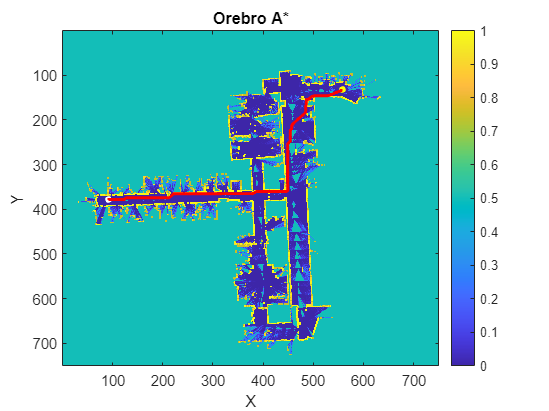


% Plot the occupancy map of fr campus
figure;
imagesc(orebroMap');
colorbar;
title('Orebro A*');
xlabel('X');
ylabel('Y');
hold on;
plot(startIndices(1), startIndices(2), 'wo', 'MarkerSize', 4, 'MarkerFaceColor', 'w');
plot(goalIndices(1), goalIndices(2), 'yo', 'MarkerSize', 4, 'MarkerFaceColor', 'y');


% pltoing the Maze after applying Dijkstra. 
hold on;
if size(pathAStar, 1) > 0
    plot(pathAStar(:, 1), pathAStar(:, 2), 'r', 'LineWidth', 2);
end
hold off;

**Dijkstra Orebro**

[rowIndices, colIndices] = find(orebroMap < 0.1);
indices = [rowIndices, colIndices];


%startIndices = indices(randi(size(indices, 1)), :);
%goalIndices = indices(randi(size(indices, 1)), :);
startIndices = [91, 379];
goalIndices = [558, 133];

obstacleMap = orebroMap;
for i = 1:size(obstacleMap, 1)
    for j = 1:size(obstacleMap, 2)
        if obstacleMap(i, j) > 0.4
            obstacleMap(i, j) = Inf;
        end
    end
end

% run Dijkstra's algorithm
disp("Orebro Dijkstra")

Orebro Dijkstra


tic
pathDijkstra = Dijkstra(obstacleMap, startIndices, goalIndices);

PushCounter: 68224
PopCounter: 67114


toc

Elapsed time is 167.642500 seconds.


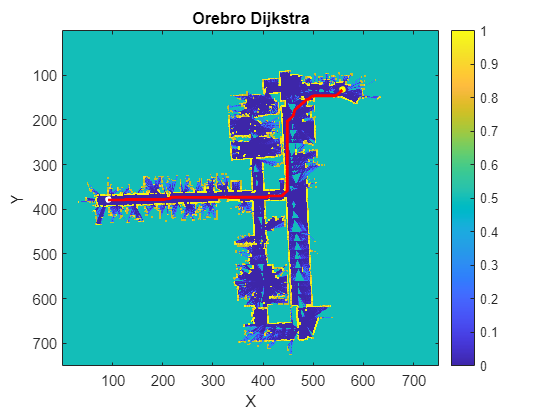


% Plot the occupancy map of fr campus
figure;
imagesc(orebroMap');
colorbar;
title('Orebro Dijkstra');
xlabel('X');
ylabel('Y');
hold on;
plot(startIndices(1), startIndices(2), 'wo', 'MarkerSize', 4, 'MarkerFaceColor', 'w');
plot(goalIndices(1), goalIndices(2), 'yo', 'MarkerSize', 4, 'MarkerFaceColor', 'y');


% pltoing the Maze after applying Dijkstra. 
hold on;
if size(pathDijkstra, 1) > 0
    plot(pathDijkstra(:, 1), pathDijkstra(:, 2), 'r', 'LineWidth', 2);
end
hold off;

**A* fr campus**

[rowIndices, colIndices] = find(frCampusMap < 0.1);
indices = [rowIndices, colIndices];


%startIndices = indices(randi(size(indices, 1)), :);
%goalIndices = indices(randi(size(indices, 1)), :);
startIndices = [36, 202];
goalIndices = [247, 70];

obstacleMap = frCampusMap;
for i = 1:size(obstacleMap, 1)
    for j = 1:size(obstacleMap, 2)
        if obstacleMap(i, j) > 0.25
            obstacleMap(i, j) = Inf;
        end
    end
end

% run A* algorithm
disp("fr campus A*")

fr campus A*


tic
pathAStar = AStar(obstacleMap, startIndices, goalIndices);

PushCounter: 13861
PopCounter: 8111


toc

Elapsed time is 10.605265 seconds.


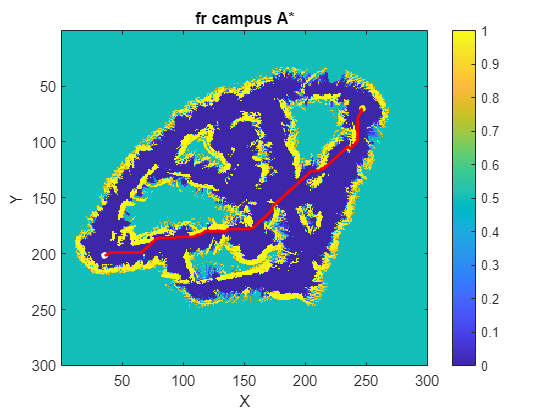


% Plot the occupancy map of fr campus
figure;
imagesc(frCampusMap');
colorbar;
title('fr campus A*');
xlabel('X');
ylabel('Y');
hold on;
plot(startIndices(1), startIndices(2), 'wo', 'MarkerSize', 4, 'MarkerFaceColor', 'w');
plot(goalIndices(1), goalIndices(2), 'yo', 'MarkerSize', 4, 'MarkerFaceColor', 'y');


% pltoing the Maze after applying Dijkstra. 
hold on;
if size(pathAStar, 1) > 0
    plot(pathAStar(:, 1), pathAStar(:, 2), 'r', 'LineWidth', 2);
end
hold off;

**Dijkstra's fr campus**

[rowIndices, colIndices] = find(frCampusMap < 0.1);
indices = [rowIndices, colIndices];


%startIndices = indices(randi(size(indices, 1)), :);
%goalIndices = indices(randi(size(indices, 1)), :);
startIndices = [36, 202];
goalIndices = [247, 70];

obstacleMap = frCampusMap;
for i = 1:size(obstacleMap, 1)
    for j = 1:size(obstacleMap, 2)
        if obstacleMap(i, j) > 0.4
            obstacleMap(i, j) = Inf;
        end
    end
end

% run Djikstra's algorithm
disp("fr campus Dijkstra")

fr campus Dijkstra


tic
pathDijkstra = Dijkstra(obstacleMap, startIndices, goalIndices);

PushCounter: 21324
PopCounter: 20577


toc

Elapsed time is 8.603113 seconds.


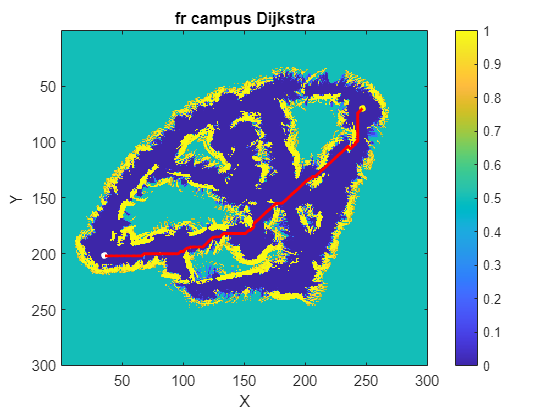


% Plot the occupancy map of fr campus
figure;
imagesc(frCampusMap');
colorbar;
title('fr campus Dijkstra');
xlabel('X');
ylabel('Y');
hold on;
plot(startIndices(1), startIndices(2), 'wo', 'MarkerSize', 4, 'MarkerFaceColor', 'w');
plot(goalIndices(1), goalIndices(2), 'yo', 'MarkerSize', 4, 'MarkerFaceColor', 'y');


% pltoing the Maze after applying Dijkstra. 
hold on;
if size(pathDijkstra, 1) > 0
    plot(pathDijkstra(:, 1), pathDijkstra(:, 2), 'r', 'LineWidth', 2);
end
hold off;

**Inflates the occupied cells to enhance and optimize path planning**

function inflatedMap = InflateMap(map, radius)
    % Get the size of the map
    [mapHeight, mapWidth] = size(map);
    
    % Create a copy of the original map to store the inflated values
    inflatedMap = map;
    
    % Iterate over each cell in the map
    for i = 1:mapHeight
        for j = 1:mapWidth
            if map(i, j) > 0.5
                % Inflate values to neighboring cells within the specified radius
                for di = -radius:radius
                    for dj = -radius:radius
                        % Calculate the coordinates of the neighboring cell
                        ni = i + di;
                        nj = j + dj;
                        
                        % Check if the neighboring cell is within the map boundaries
                        if ni >= 1 && ni <= mapHeight && nj >= 1 && nj <= mapWidth
                            % Apply the inflation value to the neighboring cell
                            inflatedMap(ni, nj) = map(i, j);
                        end
                    end
                end
            end
        end
    end
end
